# Test/ Debugger: imgCropMULTI 

**Summary: **Works through step by step the preprocessing and cropping stages. Useful for code debugging and investigating preprocessing quality of a particular frame.

**User notes:**

1) Make sure relevant function files, videos and individual video frames are located in the same folder as this live script. So far, only works on horizontal flow videos.

2) There are some user-defined inputs, particularly video/ image file name. Other processing parameters can also be adjusted as see fit.

V2.0. SWC, 19 Feb 2021.

close all 
clear

## 1) Load video

vid_file_name = 'C12T005_SO5cSt 12uL_23 uL C12TAB_50mM  27.avi'; %<-------- user-defined input!!
% vid_file_name = 'DYE003_52%Gl_W_0.003_Ink_SO_SPAN80_0.003_2kfps_.avi';
vid = VideoReader(vid_file_name); %read video 
totframes = vid.NumFrames %check total num of frames in video

totframes = 1152

## 2a) Background generation - 'Basic' Statistical Approach

Shows 3 methods: i) Median, ii) Mode and iii) Mean

Processed video: C12T005_SO5cSt 12uL_23 uL C12TAB_50mM  27.avi
Median; Elapsed time = 3.22
Mode; Elapsed time = 4.80
Mean; Elapsed time = 5.73


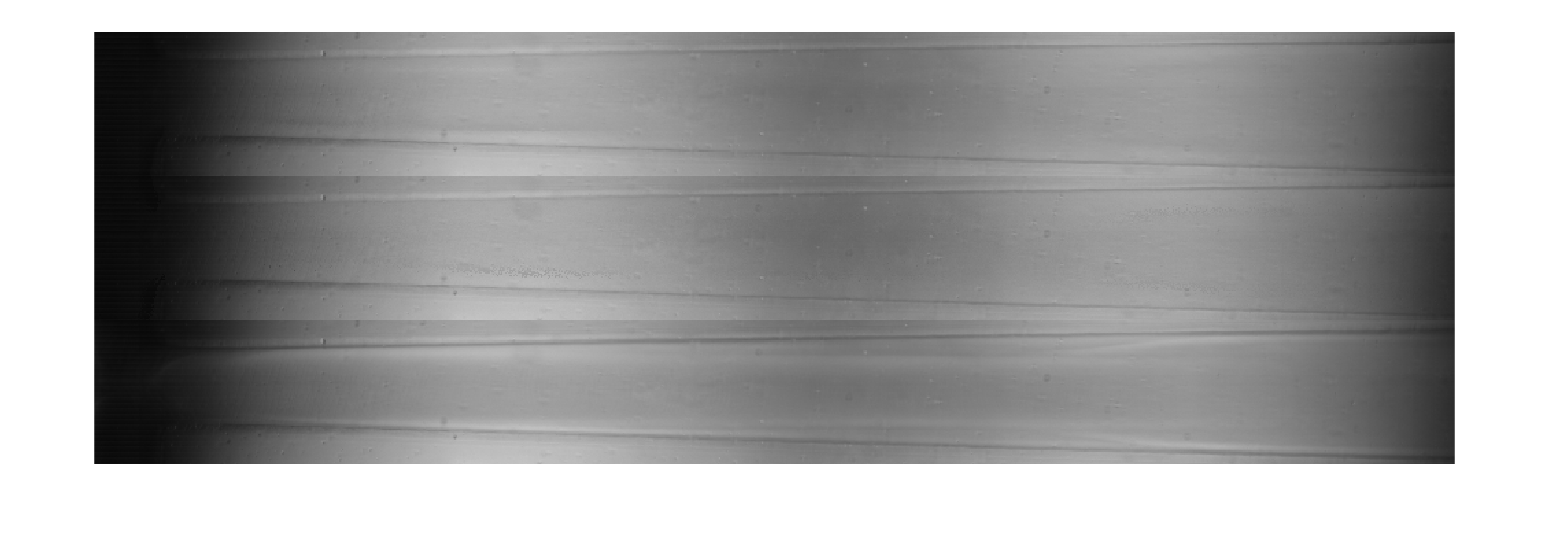

n = 150;    % number of frames to use for background generation  <-------- user-defined input!!

[med_bg mod_bg avg_bg] = bgGenBasic(vid_file_name,n); %custom function

## 2b) Background generation - 'Complex' Statistical Approach

### (Adapted from ADM method)

n = 40;    % number of frames to use for background generation <-------- user-defined input!!

bg = bgGenCmplx(vid_file_name,n,'modified'); %custom function

Processed video: C12T005_SO5cSt 12uL_23 uL C12TAB_50mM  27.avi
Using modified algorithm...
Elapsed time is 11.191827 seconds.


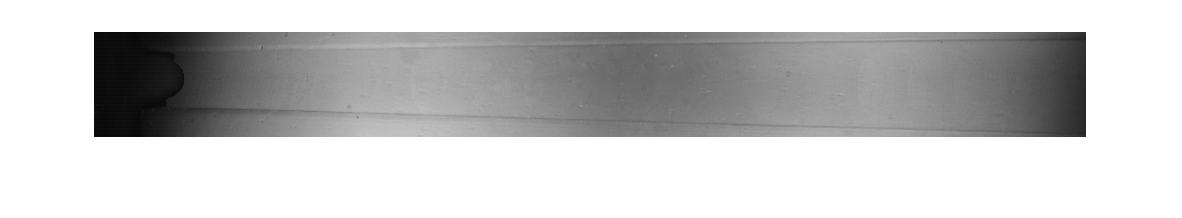

% 'original': for WAT, TRI, SDS, DYE.
% 'modified': for C12Tab.

figure; imshow(bg);

## 3) Load test image 

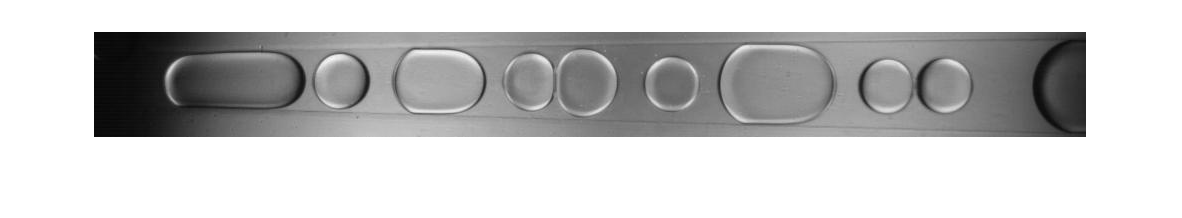

% Load images
% I = imread('C12T005_745.jpg');   %<-------- user-defined input!!
I = read(vid,randperm(totframes,1)); % load a random image

% check image loaded 
figure; imshow(I);  

## 4) Background Subtraction

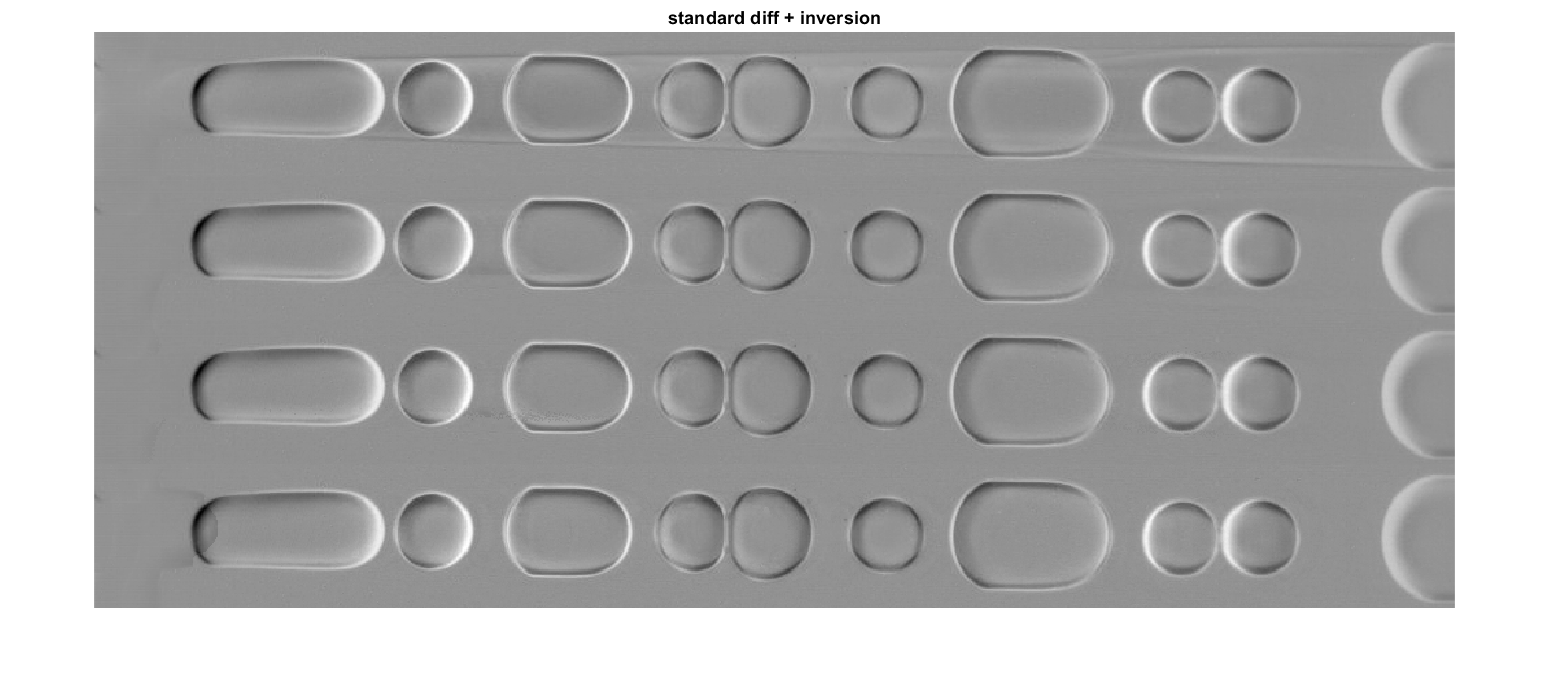

%% From Mean background generation
subMean = rescale(1-(double(I) - double(avg_bg))); % std diff with inversion
subMean2 = rescale(abs(double(I) - double(avg_bg))); % abs subtraction

%% From Median background generation
subMed = rescale(1-(double(I) - double(med_bg))); % std diff with inversion
subMed2 = rescale(abs(double(I) - double(med_bg))); % abs diff

%% From Mode background generation
subMax = rescale(1-(double(I) - double(mod_bg))); % std diff with inversion
subMax2 = rescale(abs(double(I) - double(mod_bg))); % abs diff

%% From complex background generation method 
subCom = rescale(1-(double(I) - double(bg))); % std diff with inversion
subCom2 = rescale(abs(double(I) - double(bg))); % absdiff

figure; 
montage({subMean subMed subMax subCom}, 'Size', [4 1]); title('standard diff + inversion');

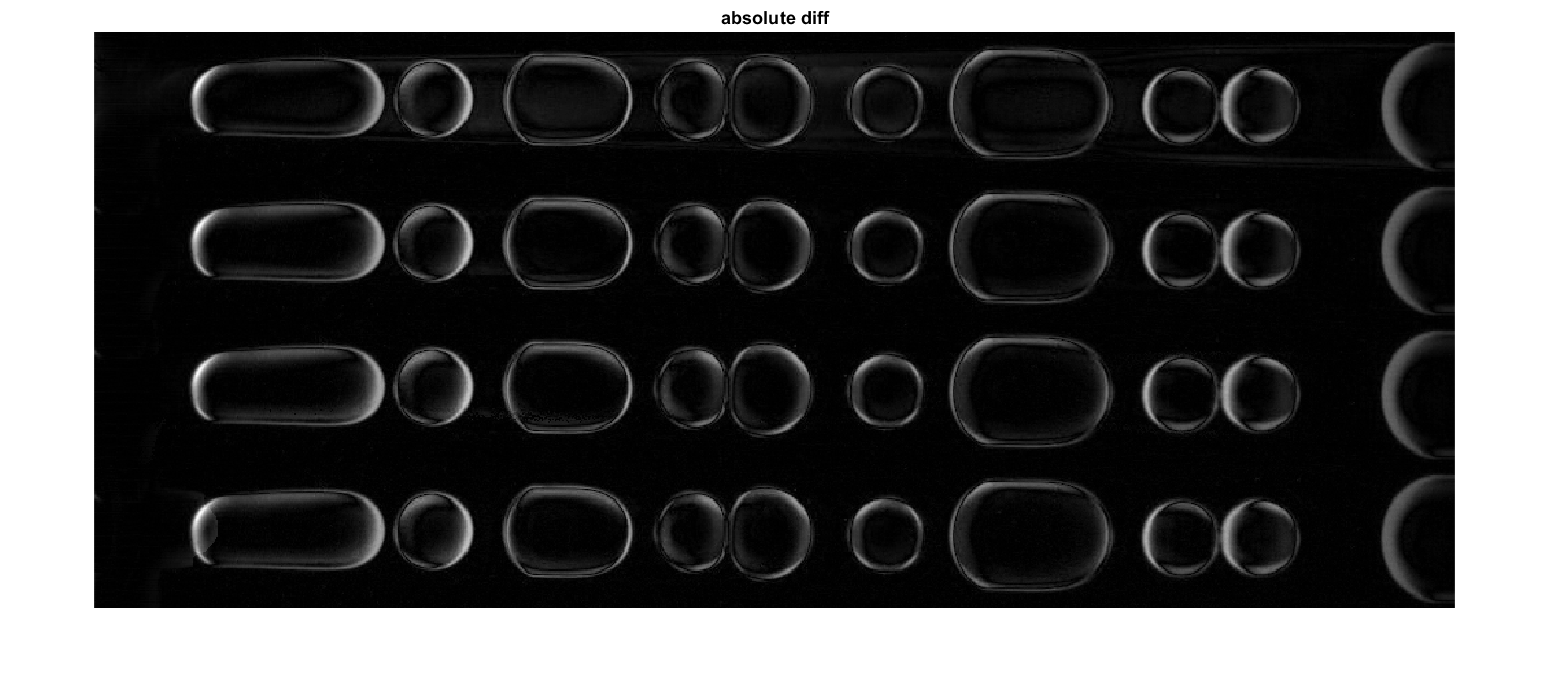

figure; montage({subMean2 subMed2 subMax2 subCom2}, 'Size', [4 1]); title('absolute diff');


% figure; imshow(subMean); title('mean')
% figure; imshow(subMed); title('median')
% figure; imshow(subMax); title('mode')
% figure; imshow(subCom); title('complex')

## 5) Convert to binary image

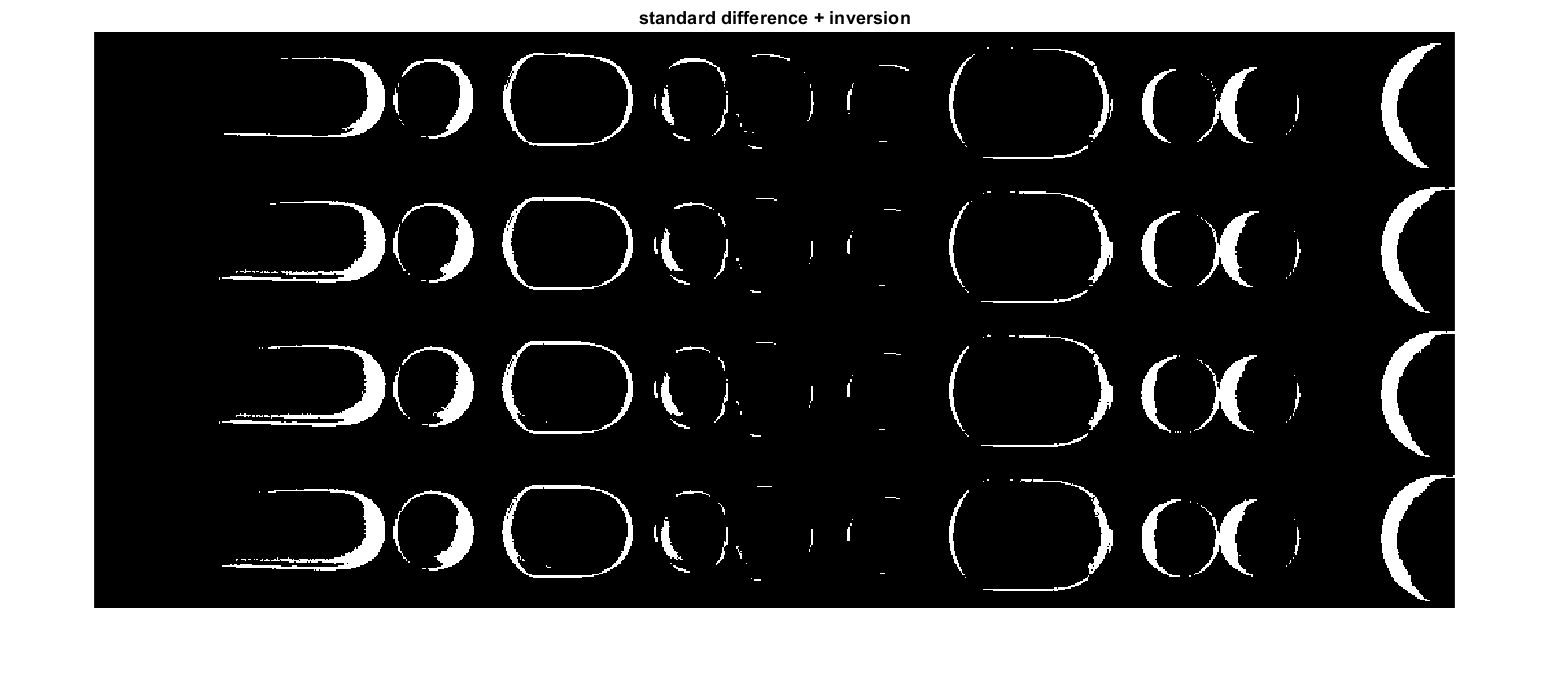

bin1 = imbinarize(imadjust((subMean)), graythresh(subMean));  %graythresh uses Otsu's Method
bin2 = imbinarize(imadjust((subMed)), graythresh(subMed)); 
bin3 = imbinarize(imadjust((subMax)), graythresh(subMax)); 
bin4 = imbinarize(imadjust((subCom)), graythresh(subCom)); 

figure; montage({bin1 bin2 bin3 bin4}, 'Size', [4 1]); title('standard difference + inversion');

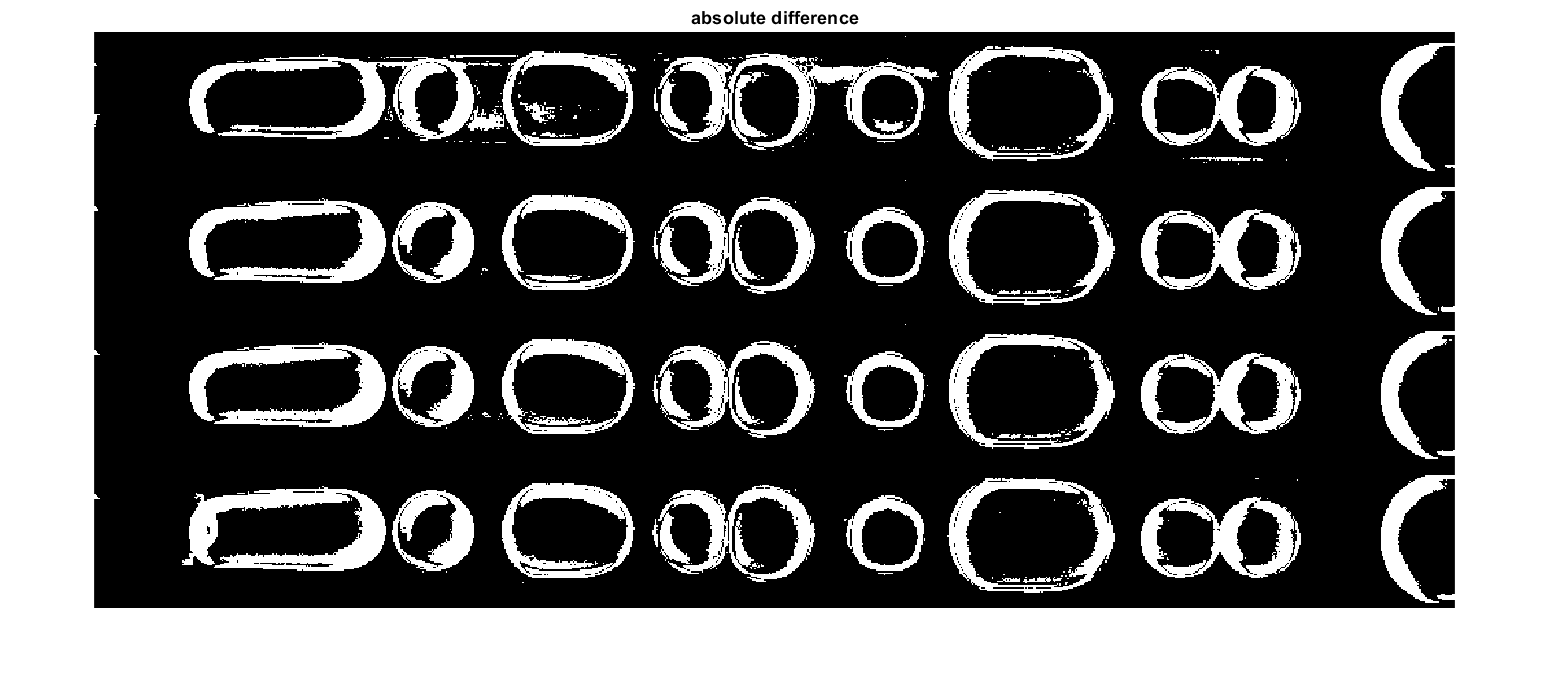

bin21 = imbinarize(imadjust((subMean2)), graythresh(subMean2)); 
bin22 = imbinarize(imadjust((subMed2)), graythresh(subMed2)); 
bin23 = imbinarize(imadjust((subMax2)), graythresh(subMax2)); 
bin24 = imbinarize(imadjust((subCom2)), graythresh(subCom2)); 

figure; montage({bin21 bin22 bin23 bin24}, 'Size', [4 1]); title('absolute difference');

## 6) Morphological fill

- only use best result from previous parts

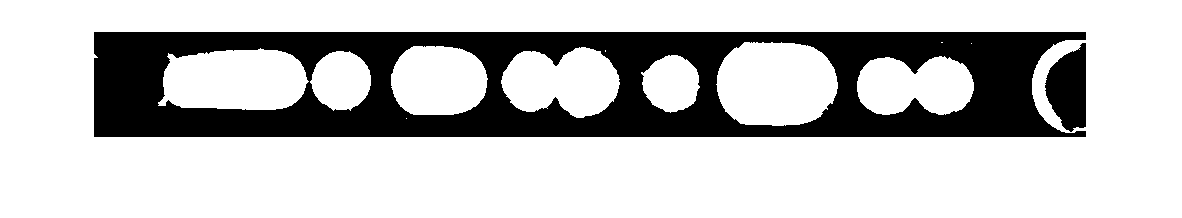

Img = bin24; % choose a  binary image to process

fill1 = imfill(imclose(Img, strel('disk',2)), 'holes'); %fill fully closed drops
figure; imshow(fill1)

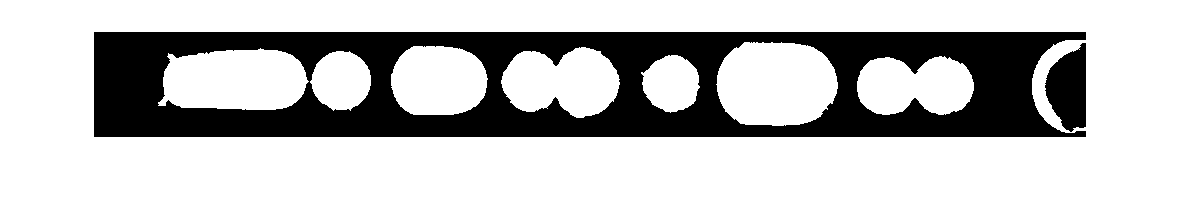

minA = 50; % anything with area less than this will be treated as noise object
cfill1 = bwareaopen(fill1,minA); %noise object removal
figure; imshow(cfill1);

rg = regionprops('table',cfill1,'Area') %detect ROI

rg = 8×1 table
    Area
    ____

    7682
    2763
    5613
    6148
    2507
    8487
    5422
    1603



[bwl n] = bwlabel(cfill1,8); %assign label to each detected ROI

minA = 0.2*max(rg.Area)

minA = 1.6974e+03

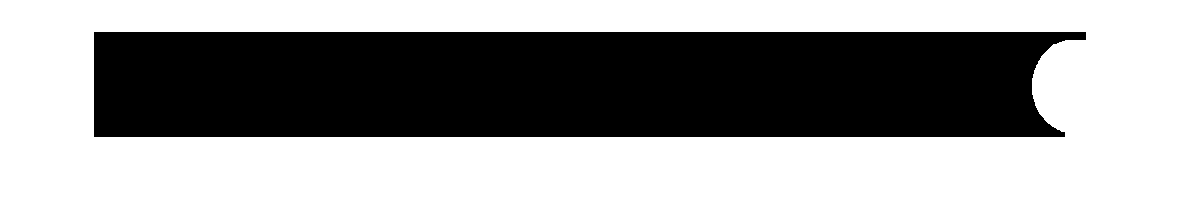

pos = find(rg.Area < minA); %find ROIs that have holes so have not been filled; 
 
bwl2 = ismember(bwl,pos); %segment out ROIs that need further manipulation (morphological close)
% figure; imshow(bwl2);

bwl2 = imclose(bwl2,strel('disk',15)); %morphological close 
fill2 = imfill(bwl2,'holes'); %fill fully closed drops (drops at border not filled!)
% figure; imshow(fill2)

fill2_bord = fill_border_drops(bwl2); % fill objects at border (custom function)
% figure; imshow(fill2_bord)

fill2 = fill2 | fill2_bord; %resulting filled image
figure; imshow(fill2);

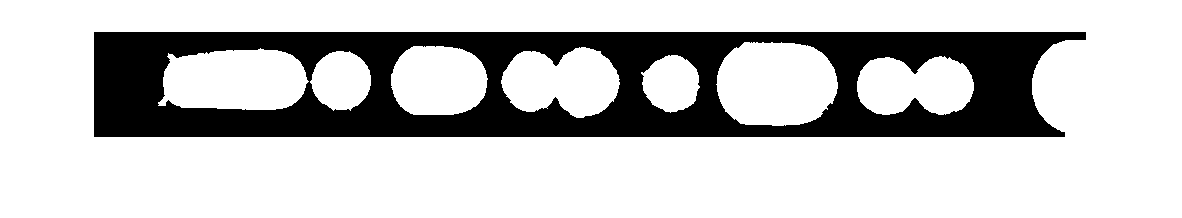


L = cfill1 | fill2; %combine to form a final mask
figure; imshow(L);  

## 7) Drop Segmentation 

- attempt to separate drops that were wrongly fused together from previous steps

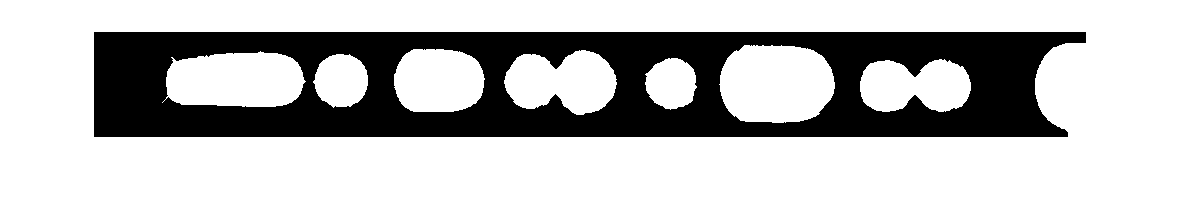

L2 = imerode(L, strel('diamond',3));
figure; imshow(L2)

## 8) Identify Bounding Box of ROI

ROI = regionprops('table', L2)

ROI = 8×3 table
    Area        Centroid                  BoundingBox           
    ____    ________________    ________________________________

    6612    142.08    48.822     68.5     19.5      144       56
    2279    247.82     49.19    219.5     22.5       55       54
    4877    344.98    49.363    300.5     17.5       91       63
    5271    468.73    50.568    410.5     18.5      113       65
    2039    577.99    52.171    551.5     26.5       52       52
    7567     682.6    52.459    625.5     13.5      116       78
    4574    821.46     54.48    766.5     27.5      111       53
    3911    970.47    56.461    941.5     11.5       51       94


% first entry in ROI table is the drop nearest to left frame border
leadEdge = ROI.Centroid(1,1) + 1.4*(ROI.BoundingBox(1,3) /2)  % estimate point of entrance to main channel

leadEdge = 242.8809

% remove any drops outside of main flow channel 
ROI(ROI.Centroid(:,1) < leadEdge, :) = []

ROI = 7×3 table
    Area        Centroid                  BoundingBox           
    ____    ________________    ________________________________

    2279    247.82     49.19    219.5     22.5       55       54
    4877    344.98    49.363    300.5     17.5       91       63
    5271    468.73    50.568    410.5     18.5      113       65
    2039    577.99    52.171    551.5     26.5       52       52
    7567     682.6    52.459    625.5     13.5      116       78
    4574    821.46     54.48    766.5     27.5      111       53
    3911    970.47    56.461    941.5     11.5       51       94


% remove small objects
ROI(ROI.Area < 200, :) = []

ROI = 7×3 table
    Area        Centroid                  BoundingBox           
    ____    ________________    ________________________________

    2279    247.82     49.19    219.5     22.5       55       54
    4877    344.98    49.363    300.5     17.5       91       63
    5271    468.73    50.568    410.5     18.5      113       65
    2039    577.99    52.171    551.5     26.5       52       52
    7567     682.6    52.459    625.5     13.5      116       78
    4574    821.46     54.48    766.5     27.5      111       53
    3911    970.47    56.461    941.5     11.5       51       94


Assumptions: 

- horizontal flow in main channel 

- entrance region is captured in video (i.e., video does not just purely show a segment of main flow - like in C12Tab videos)

- drop identified as that nearest to left frame border is not a random noise object (and thus the width is not representative of a regular drop)

## 9) Plot results

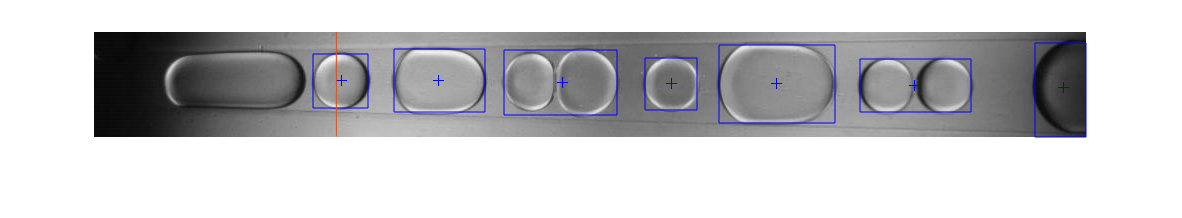

figure; imshow(I);
hold on

% visualise centroid
plot(ROI.Centroid(:,1), ROI.Centroid(:,2), 'b+')

% visualise bounding box
for i=1:height(ROI)
    rectangle('Position',ROI.BoundingBox(i,:),'EdgeColor','b')
end


% visualise estimated leading edge for analysed region
plot([leadEdge leadEdge], [0 vid.Height])

## 6) Crop and show individual drops 

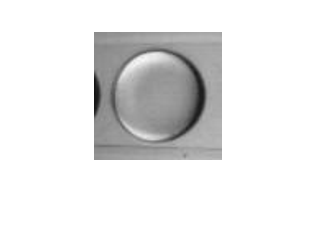

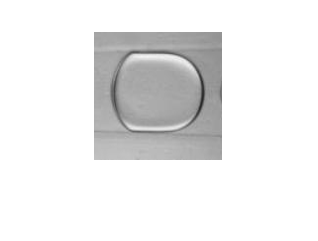

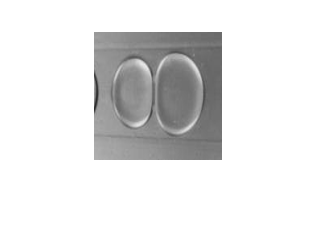

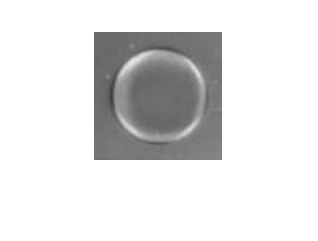

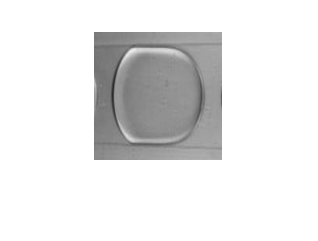

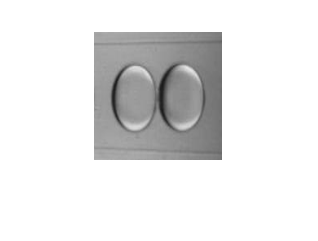

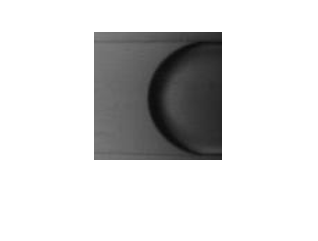

roiTable = ROI.BoundingBox; 
cropSize = [128 128];

for i = 1: height(roiTable)
    dim = 1.4*max([roiTable(i,3:4)]); % this will be the width/ height of square cropped area
    
    % x-coord of centroid of cropping region
    cx = roiTable(i,1) + roiTable(i,3)/2; 
    % y-coord of centroid of cropping region
    cy = roiTable(i,2) + roiTable(i,4)/2; 
    
    % coordinates of bottom-left vertex of intended crop region 
    xmin = cx - dim/2 ;
    ymin = cy - dim/2 ; 
    
    % crop region defined as [x-coord of bottom left point, y-coord of
    % bottom left point, width, height]
    Img = imcrop(I, [xmin, ymin, dim, dim]);
    
    % resize cropped image
    Img = imresize(Img, cropSize);
    
    %show image

    figure; imshow(Img)
end 